%% ========== Matlab code sample for Practicum 1 Spring2021===========
%Program by Robert L. Bara  TUID:915614617  Email: tuj22026@temple.edu
% Simulation: Testing Microprocessors
close all
clear all
clc
range_x = [1:4]; %Grade Range 

## Iterating across 1000 microprocessors with various grades

n=1e3; %Number of Microprocessors
for ii=1:n
    processors=randi(4,1); %The sample of processors to be tested
    x(ii)=processors;
    if x(ii)==1      %Grade=1 with probability of 0.1
        y(ii)=0.1;
    elseif x(ii)==2 %Grade=2 with probability of 0.2
        y(ii)=0.2;    
    elseif x(ii)==3 %Grade=3 with probability of 0.3
        y(ii)=0.3;    
    else            %Grade=4 with probability of 0.4
        y(ii)=0.4;
    end
end


% Calculations by MATLAB
mean_y_sim=sum(y)/n

mean_y_sim = 0.2498

std_y_sim=sqrt(sum((y-mean_y_sim).^2)/n)

std_y_sim = 0.1096

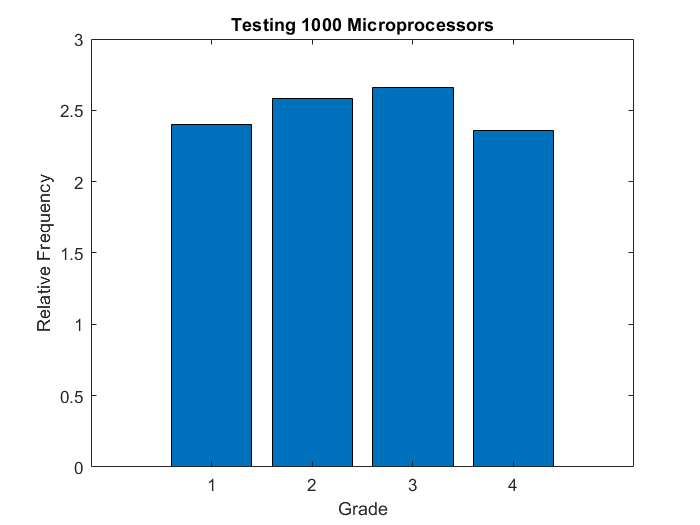



%The conditional probability P[X=3|X>=2]=P[X=3∩X>=2]/P[X>=2]
%The intersection of X>=2 and X=3, will be X=3
%Processors out of 1000
g3=sum(x==3); %how many processors are grade 3
g2=sum(x==2); %how many processors are grade 2
g4=sum(x==4); %how many processors are grade 4
g1=sum(x==1); %how many processors are grade 1

d=g3+g2+g4; %how many processors are grade 2 or more
P_3=g3*0.3; %Probability P(X=3)
P_2orMore=(g2*0.2)+(g3*0.3)+(g4*0.4); %Probability P(X>=2)
%Conditional Probability calculation
P_32=P_3/P_2orMore;


%Plotting Histograph and Analysis
figure(1)
hist_x = hist(x, range_x);  
bar(range_x,((hist_x*10)/n));
title('Testing 1000 Microprocessors')
xlabel('Grade')
ylabel('Relative Frequency')


fprintf('Mean of Y by MATLAB: %f\n',mean_y_sim);

Mean of Y by MATLAB: 0.249800


fprintf('Standard Dev of Y by MATLAB: %f\n',std_y_sim);

Standard Dev of Y by MATLAB: 0.109636


fprintf('There are %d Grade 3 and %d Grade 2 or higher Microrocessors\n',g3,d);

There are 266 Grade 3 and 760 Grade 2 or higher Microrocessors


fprintf('Therefore, P[x=3|x>=2]=P[X=3∩X>=2]/P[X>=2], which equals %d\n',P_32);

Therefore, P[x=3|x>=2]=P[X=3∩X>=2]/P[X>=2], which equals 3.534101e-01


## For 10000 processors

n1=10e3; %Number of Microprocessors
for iii=1:n1
    processors_10000=randi(4);
    x1(iii)=processors_10000;
    if x1(iii)==1      %Grade=1 with probability of 0.1
        y1(iii)=0.1;
    elseif x1(iii)==2 %Grade=2 with probability of 0.2
        y1(iii)=0.2;    
    elseif x1(iii)==3 %Grade=3 with probability of 0.3
        y1(iii)=0.3;    
    else            %Grade=4 with probability of 0.4
        y1(iii)=0.4;
    end
end


% Calculations by MATLAB
mean_y_sim_10000=sum(y1)/n1

mean_y_sim_10000 = 0.2497

std_y_sim_10000=sqrt(sum((y1-mean_y_sim_10000).^2)/n1)

std_y_sim_10000 = 0.1112

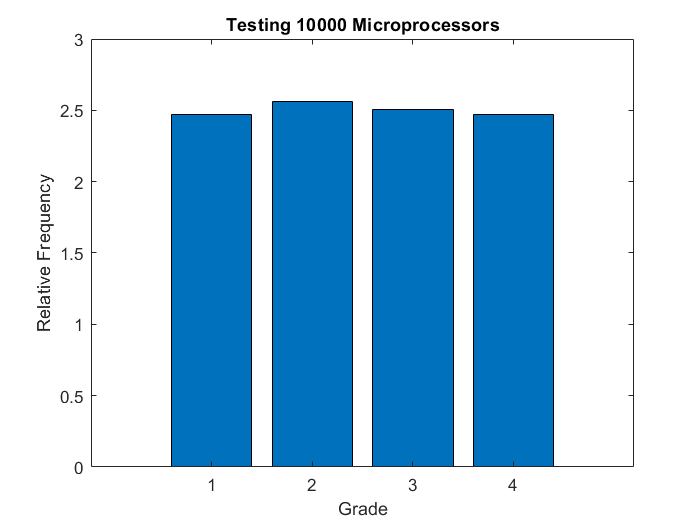


%The conditional probability P[X=3|X>=2]=P[X=3∩X>=2]/P[X>=2]
%The intersection of X>=2 and X=3, will be X=3
%Processors out of 10000
g3_1=sum(x==3); %how many processors are grade 3
g2_1=sum(x==2); %how many processors are grade 2
g4_1=sum(x==4); %how many processors are grade 4
g1_1=sum(x==1); %how many processors are grade 1

d1=g3_1+g2_1+g4_1; %how many processors are grade 2 or more
P_3_1=g3_1*0.3; %conditional probability P(X=3)
P_2orMore_1=(g2_1*0.2)+(g3_1*0.3)+(g4_1*0.4); %Conditional Probability P(X>=2)
%Conditional Probability calculation
P_32_1=P_3_1/P_2orMore_1; 

%Plotting Histograph and Analysis
figure(2)
hist_x1 = hist(x1, range_x);  
bar(range_x,(hist_x1*10)/n1);
title('Testing 10000 Microprocessors')
xlabel('Grade')
ylabel('Relative Frequency')


fprintf('Mean of Y by MATLAB: %f\n',mean_y_sim_10000);

Mean of Y by MATLAB: 0.249740


fprintf('Standard Dev of Y by MATLAB: %f\n',std_y_sim_10000);

Standard Dev of Y by MATLAB: 0.111238


fprintf('There are %d Grade 3 and %d Grade 2 or higher Microrocessors\n',g3_1,d1);

There are 266 Grade 3 and 760 Grade 2 or higher Microrocessors


fprintf('Therefore, P[x=3|x>=2]=P[X=3∩X>=2]/P[X>=2], which equals %d\n',P_32_1);

Therefore, P[x=3|x>=2]=P[X=3∩X>=2]/P[X>=2], which equals 3.534101e-01


## Calculating Percent Differences between Simulation and Calculations


%for 1000 Microprocesors
MeanSim=mean_y_sim;
MeanCalc=0.2498;
stdSim=std_y_sim;
stdCalc=7.8915;
probSim=P_32;
probCalc=0.3534;

%Percent Differences
MeanDiff=(abs(MeanSim-MeanCalc)/((MeanSim+MeanCalc)/2))*100

MeanDiff = 1.9402

stdDiff=(abs(stdSim-stdCalc)/((stdSim+stdCalc)/2))*100

stdDiff = 194.4620

probDiff=(abs(probSim-probCalc)/((probSim+probCalc)/2))*100

probDiff = 1.7282


%for 10000 Microprocesors
MeanSim10k=mean_y_sim_10000;
MeanCalc10k=0.025;
stdSim10k=std_y_sim_10000;
stdCalc10k=2.4977;
probSim10k=P_32_1;
probCalc10k=0.3534;

%Percent Differences
MeanDiff1000=(abs(MeanSim10k-MeanCalc10k)/((MeanSim10k+MeanCalc10k)/2))*100

MeanDiff1000 = 163.7773

stdDiff10000=(abs(stdSim10k-stdCalc10k)/((stdSim10k+stdCalc10k)/2))*100

stdDiff10000 = 182.8786

probDiff10000=(abs(probSim-probCalc10k)/((probSim10k+probCalc10k)/2))*100

probDiff10000 = 1.7282